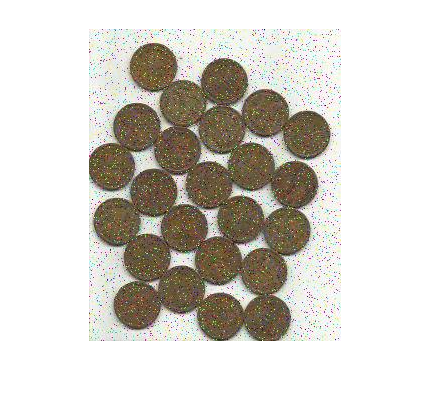

% T = graythresh(I) computes a global threshold T from grayscale
% image I, using Otsu's method [1]. Otsu's method chooses a threshold
% that minimizes the intraclass variance of the thresholded black and
% white pixels. The global threshold T can be used with imbinarize to
% convert a grayscale image to a binary image.

im = imread("D:\Projects\computer-vision\Lab 5\corrupted_coins.jpg");
imshow(im)

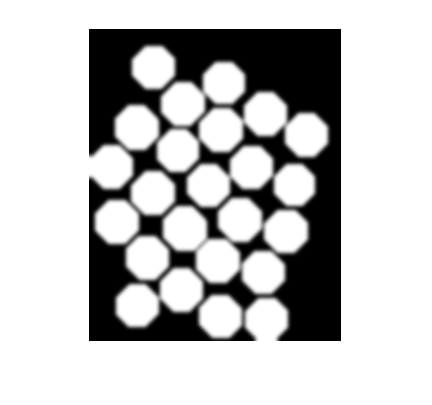

imP = Process1(im);
imshow(imP)

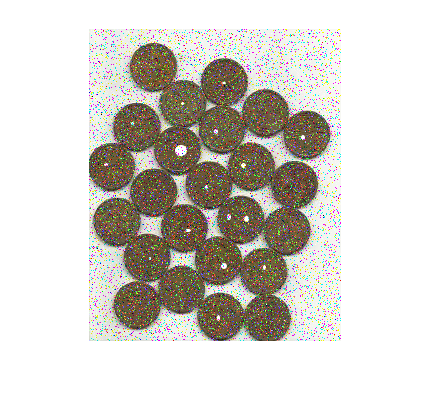


im = imread("D:\Projects\computer-vision\Lab 5\holes_corrupted_coins.png");
imshow(im)

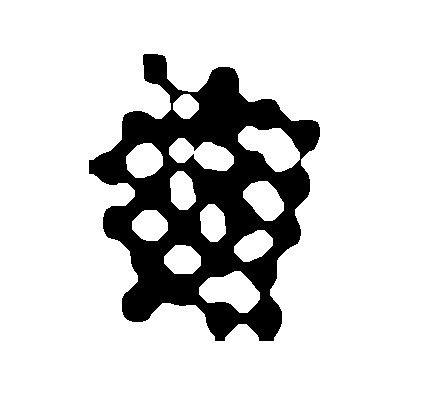

% imP = Process2(im);
imP = Process2(im);

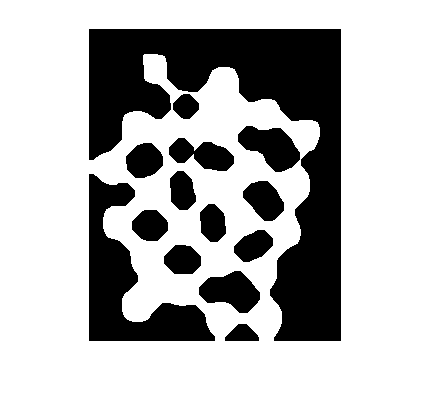

imshow(~imP)

function imP = Process1(im)
    % Convert to greyscale
    imP = rgb2gray(im);    

    % Apply gaussian blur
    imP = medfilt2(imP);

    % Otsu's Graythresh
    level = graythresh(imP);
    imP = imbinarize(imP,level);
    
    % Morphological ops
    imP = imfill(imP, 'holes');
    
    % Morphological ops
    se = strel('disk',22);
    imP = imclose(imP, se);
    
    se = strel('disk',3);
    imP = imdilate(imP, se);
    
    se = strel('disk',19);
    imP = imclose(imP, se);
    
    se = strel('disk',2);
    imP = imdilate(~imP, se);
    
    imP = imgaussfilt(double(imP), 2);
    
end

function imP = Process2(im)
    % Convert to greyscale
    imP = rgb2gray(im);   
    
    imP = histeq(imP);
    
    % Apply gaussian blur
    imP = imgaussfilt(imP, 3);
%     
%     se = strel('disk',2);
%     imP = imdilate(imP, se);
   
    % Apply gaussian blur
    imP = imgaussfilt(imP, 4);

    imP = histeq(imP);
    
    % Otsu's Graythresh
    level = graythresh(imP);
    imP = imbinarize(imP,level);
    
    se = strel('disk',6);
    imP = imerode(imP, se);
    
    se = strel('disk',10);
    imP = imdilate(imP, se);
  
    se = strel('disk',6);
    imP = imerode(imP, se);
    
    % Morphological ops
%     imP = ~imfill(imP, 'holes');    
    
    se = strel('disk',5);
    imP = imdilate(imP, se);
    
    se = strel('disk',3);
    imP = imerode(imP, se);
    se = strel('disk',5);
    imP = imdilate(imP, se);
    
    se = strel('disk',3);
    imP = imerode(imP, se);
    se = strel('disk',5);
    imP = imdilate(imP, se);
    
    se = strel('disk',3);
    imP = imerode(imP, se);
    se = strel('disk',1);
    imP = imdilate(imP, se);
    
    se = strel('disk',8);
    imP = imerode(imP, se);
    se = strel('disk',8);
    imP = imdilate(imP, se);

    imshow(imP)
    
end